clear all
clf;
load DelMar_data.mat

u = detrend(u',0)';
v = detrend(v',0)';   %subtract time average
data = [u' v'];
cov = data' * data;
dt = datetime(datevec(t));

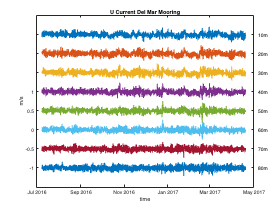

figure(1)
clf
[nz,nt] = size(u);
for j = 1:nz
    plot(dt,u(j,:)-(j-1)*.5+2)
    text(dt(end)+18,-(j-1)*.5+2,[num2str(abs(z(j))),'m'])
    hold on
end
hold off
ylabel('m/s');
set(gca,'YTickLabel',{''.','-1','-0.5','0','0.5','1','','',''})
title('U Current Del Mar Mooring')

xlabel('time');

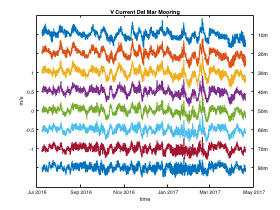

figure(2)
clf
[nz,nt] = size(v);
for j = 1:nz
    plot(dt,v(j,:)-(j-1)*.5+2)
    text(dt(end)+18,-(j-1)*.5+2,[num2str(abs(z(j))),'m'])
    hold on
end
hold off
ylabel('m/s');
set(gca,'YTickLabel',{'','',-1','-0.5','0','0.5','1','','',''})
title('V Current Del Mar Mooring')
xlabel('time');

[e,lambda] = eig(cov);        %e = eigenvectors, lambda = eigenvalues
lambda = diag(lambda);
if(lambda(1) < lambda(end))
    lambda = fliplr(lambda(:)');
    e = fliplr(e);
end
A = data*e; 

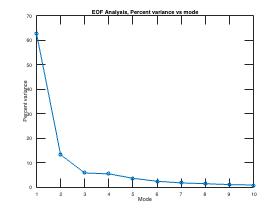

figure(3)
pvar = lambda/sum(lambda)*100;
plot(pvar,'o-','LineWidth',2);
xlim([1,10]);
set(gca,'TickDir','in');
ax = gca;
ax.YAxis.TickLabelGapOffset = 0.05;
ax.XAxis.TickLabelGapOffset = 0.05;
ylabel('Percent variance');
xlabel('Mode');
title('EOF Analysis, Percent variance vs mode');

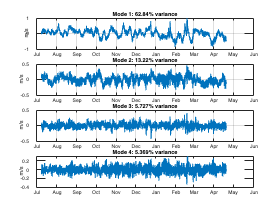

figure (4)
for j = 1:4
    subplot(4,1,j)
    plot(dt,A(:,j))
    grid on
    datetick
    title(['Mode ',num2str(j),': ',num2str(pvar(j),4),'% variance'])
    ylabel('m/s');
end
grid off;

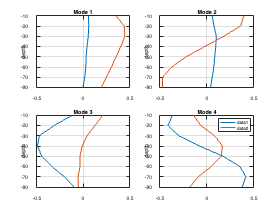

figure(5)
clf
nmode = 4;

for j = 1:nmode
    subplot(2,2,j)
    plot(e(1:8,j),z,'LineWidth',1)
    hold on;
    ylabel('depth');
    plot(e(9:16,j),z,'LineWidth',1)
    xlim([-0.5 0.5]);
    title(['Mode ',num2str(j)])
    grid on
end
legend;

data_var_mode = NaN(8,nmode);
for j = 1:nmode
    for jz = 1:8
        data_var_modeu(jz,j) = var(A(:,j)*e(jz,j))/var(data(:,jz))*100;
    end
end

for j = 1:nmode
    for jz = 9:16
        data_var_modev(jz-8,j) = var(A(:,j)*e(jz,j))/var(data(:,jz))*100;
    end
end

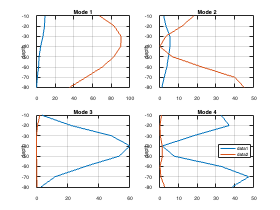

figure(6)
clf
for j = 1:nmode
    subplot(2,2,j)
    plot(data_var_modeu(:,j),z,'LineWidth',1)
    hold on;
    ylabel('depth');
    plot(data_var_modev(:,j),z,'LineWidth',1)
    title(['Mode ',num2str(j)])
    grid on
end
legend('Location','east');

### **Ans 7 : **

**Observation : Mode 1 explains major V variance at surface level. Similarly, U by Mode 3+4.**

#### **Mode 1 : **Has high magnitude and explains ~62 % of variance; it is a major force. 

It almost consitently decrease in magnitude, for both directions, with depth. This imples Mode 1 is** current driven by Wind forces.**

**Mode 2's V decreases in magnitude and changes its direction as depth increase (figure5). Thus, Profile is similar to Ekman Spiral.**

This implies mode 2 represent impact of **coriolis force** on wind stress, resultant vectors.

**Mode 3 changes sign and has few significant spikes represents, which in general, trend of water movement such as because of El-Nino and Tidal forces,. **

**Mode 4 changes rapidly over time (Fig4) represents density variation (U speed),  Tidal forces which also affects a bit V speed.**

** These changes are maximum at a particular depth**